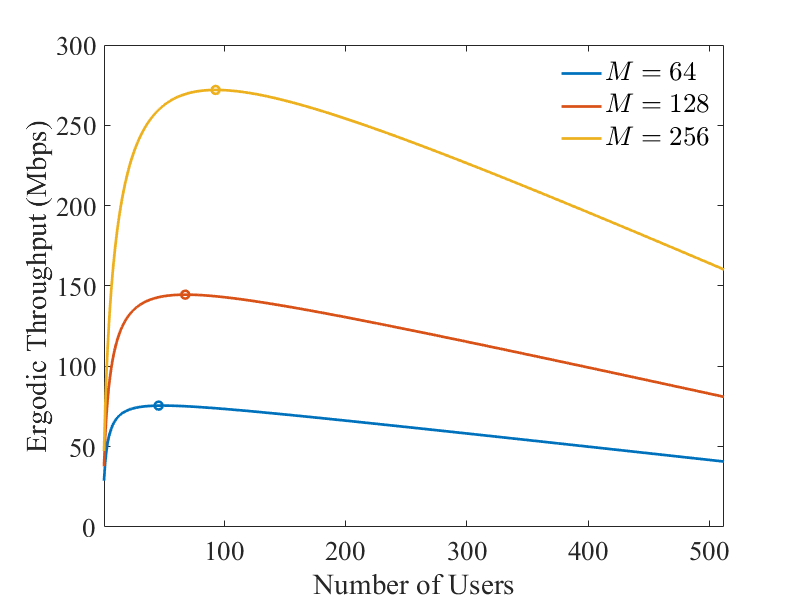

M = [64 128 256];
K = 512;
L = 1:K;

B = 20e6;

rho_db = -10;
rho    = 10^(rho_db/10);

tau_c = 1000;
tau_p = L;
ratio_dl_ul = 0.5;

se_iid_rayleigh = @(tau_p,tau_c,L,M,rho) B*ratio_dl_ul*(1 - tau_p/tau_c).*L.*log2(1 + rho*M./(L + rho*(L-1)));

linewidth  = 2;
markersize = 10;
fontname   = 'Times New Roman';
fontsize   = 20;

colours = [0.0000 0.4470 0.7410;
           0.8500 0.3250 0.0980;
           0.9290 0.6940 0.1250;
           0.4940 0.1840 0.5560;
           0.4660 0.6740 0.1880;
           0.3010 0.7450 0.9330;
           0.6350 0.0780 0.1840];

figure;

set(gcf,'position',[0 0 800 600]);
           
plot(L,se_iid_rayleigh(tau_p,tau_c,L,M(1),rho)/1e6,'color',colours(1,:),'linewidth',linewidth);
hold on;
plot(L,se_iid_rayleigh(tau_p,tau_c,L,M(2),rho)/1e6,'color',colours(2,:),'linewidth',linewidth);
plot(L,se_iid_rayleigh(tau_p,tau_c,L,M(3),rho)/1e6,'color',colours(3,:),'linewidth',linewidth);
plot(46,se_iid_rayleigh(46,tau_c,46,M(1),rho)/1e6,'o','color',colours(1,:),'linewidth',linewidth)
plot(68,se_iid_rayleigh(68,tau_c,68,M(2),rho)/1e6,'o','color',colours(2,:),'linewidth',linewidth)
plot(93,se_iid_rayleigh(93,tau_c,93,M(3),rho)/1e6,'o','color',colours(3,:),'linewidth',linewidth)
hold off;

xlabel('Number of Users','fontname',fontname,'fontsize',fontsize);
ylabel('Ergodic Throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

legend({'$M = 64$','$M = 128$', '$M = 256$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','northeast');
legend box off;

xlim([1 K]);

set(gca,'fontname',fontname,'fontsize',fontsize);

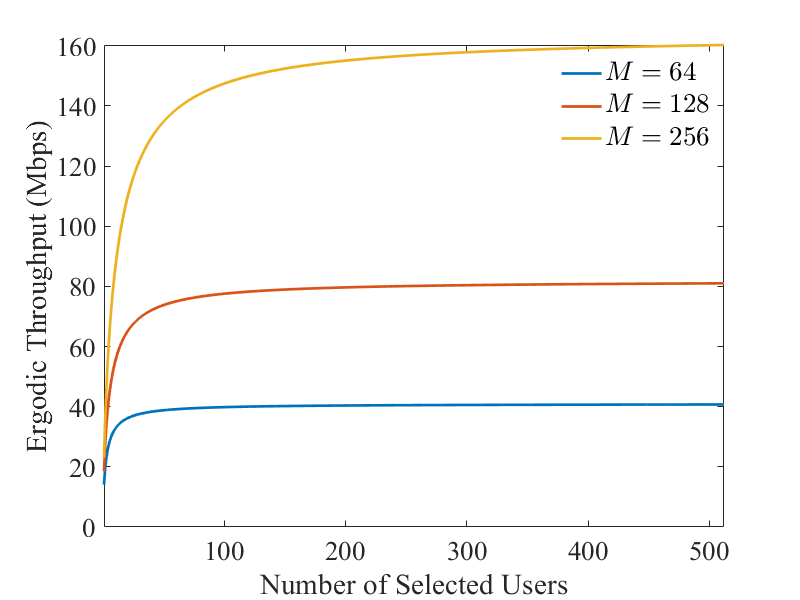

figure;

set(gcf,'position',[0 0 800 600]);

plot(L,se_iid_rayleigh(K,tau_c,L,M(1),rho)/1e6,'color',colours(1,:),'linewidth',linewidth);
hold on;
plot(L,se_iid_rayleigh(K,tau_c,L,M(2),rho)/1e6,'color',colours(2,:),'linewidth',linewidth);
plot(L,se_iid_rayleigh(K,tau_c,L,M(3),rho)/1e6,'color',colours(3,:),'linewidth',linewidth);
% plot(46,se_iid_rayleigh(46,tau_c,46,M(1),rho)/1e6,'o','color',colours(1,:),'linewidth',linewidth)
% plot(68,se_iid_rayleigh(68,tau_c,68,M(2),rho)/1e6,'o','color',colours(2,:),'linewidth',linewidth)
% plot(93,se_iid_rayleigh(93,tau_c,93,M(3),rho)/1e6,'o','color',colours(3,:),'linewidth',linewidth)
hold off;

xlabel('Number of Selected Users','fontname',fontname,'fontsize',fontsize);
ylabel('Ergodic Throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

legend({'$M = 64$','$M = 128$', '$M = 256$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','northeast');
legend box off;

xlim([1 K]);

set(gca,'fontname',fontname,'fontsize',fontsize);

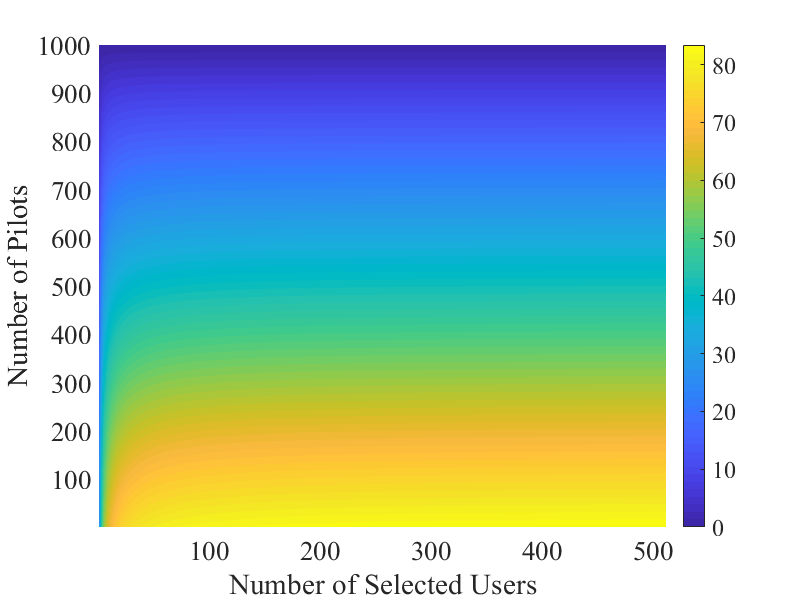

[X,Y] = meshgrid(L,1:tau_c);

figure;

set(gcf,'position',[0 0 800 600]);

surf(X,Y,se_iid_rayleigh(Y,tau_c,X,M(1),rho)/1e6,'edgecolor','none');
view(2);

xlabel('Number of Selected Users','fontname',fontname,'fontsize',fontsize);
ylabel('Number of Pilots','fontname',fontname,'fontsize',fontsize);
zlabel('Ergodic Throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

colorbar;

xlim([1 K]);
ylim([1 tau_c]);

set(gca,'fontname',fontname,'fontsize',fontsize);